% Define the values for the matrix I
I = [
    10 20 85 97 55;
    40 60 70 66 52;
    9 70 90 87 12;
    15 54 33 60 11;
    6 26 73 59 9
];

% Display the matrix
disp('Matrix I:');

Matrix I:


disp(I);

    10    20    85    97    55
    40    60    70    66    52
     9    70    90    87    12
    15    54    33    60    11
     6    26    73    59     9



% Define the matrix I
I = [
    10 20 85 97 55;
    40 60 70 66 52;
    9 70 90 87 12;
    15 54 33 60 11;
    6 26 73 59 9
];

% Define the size of the filter
filterSize = 3;

% Pad the matrix I to handle boundary cases
paddedI = padarray(I, [floor(filterSize/2), floor(filterSize/2)], 'replicate');

% Initialize matrices for mean and median filtered results
meanFiltered = zeros(size(I));
medianFiltered = zeros(size(I));

% Slide the filter over the matrix I and apply mean and median operations
for i = 1:size(I, 1)
    for j = 1:size(I, 2)
        % Extract the region of interest from the padded matrix
        region = paddedI(i:i+filterSize-1, j:j+filterSize-1);
        
        % Apply mean filter
        meanFiltered(i, j) = mean(region, 'all');
        
        % Apply median filter
        medianFiltered(i, j) = median(region, 'all');
    end
end

% Display the filtered matrices
disp('Mean Filtered Matrix:');

Mean Filtered Matrix:


disp(meanFiltered);

   24.4444   44.4444   66.6667   73.5556   64.8889
   29.7778   50.4444   71.6667   68.2222   54.2222
   34.6667   49.0000   65.5556   53.4444   40.3333
   23.3333   41.7778   61.3333   48.2222   30.0000
   17.7778   34.6667   51.4444   42.8889   26.2222



disp('Median Filtered Matrix:');

Median Filtered Matrix:


disp(medianFiltered);

    20    40    70    70    55
    20    60    70    70    55
    40    54    66    60    52
    15    33    60    59    12
    15    26    59    59    11



This MATLAB code defines the matrix I*I*, the size of the filter, and then pads the matrix to handle boundary cases. It then initializes matrices for the mean and median filtered results. The code slides the filter over the matrix I*I* and applies the mean and median operations to the regions of interest. Finally, it displays the mean and median filtered matrices.

% Define the matrix I
I = [
    10 20 85 97 55;
    40 60 70 66 52;
    9 70 90 87 12;
    15 54 33 60 11;
    6 26 73 59 9
];

% Define the size of the filter
n = 3;

% Create a Gaussian filter
sigma = sqrt(3);
[X, Y] = meshgrid(-floor(n/2):floor(n/2), -floor(n/2):floor(n/2));
gaussianFilter = exp(-(X.^2 + Y.^2) / (2 * sigma^2));
gaussianFilter = gaussianFilter / sum(gaussianFilter(:)); % Normalize the filter

% Pad the matrix I to handle boundary cases
paddedI = padarray(I, [floor(n/2), floor(n/2)], 'replicate');

% Initialize the filtered matrix
filteredMatrix = zeros(size(I));

% Slide the filter over the matrix I and apply Gaussian filtering
for i = 1:size(I, 1)
    for j = 1:size(I, 2)
        % Extract the region of interest from the padded matrix
        region = paddedI(i:i+n-1, j:j+n-1);
        
        % Apply Gaussian filter
        filteredMatrix(i, j) = sum(region(:) .* gaussianFilter(:));
    end
end

% Display the filtered matrix
disp('Filtered Matrix:');

Filtered Matrix:


disp(filteredMatrix);

   23.5613   43.4392   67.4788   74.6292   64.4924
   30.1754   50.7861   71.8584   68.7287   53.5639
   33.5798   50.1255   66.4712   55.0109   39.2378
   22.8404   41.8414   60.7933   48.6308   28.7556
   16.9929   34.6923   52.0222   44.0463   25.2464



This MATLAB code defines the matrix I*I*, the size of the Gaussian filter n*n*, and creates a Gaussian filter with σ=3*σ*=3�. It then pads the matrix I*I* to handle boundary cases and initializes a matrix for the filtered results. The code slides the Gaussian filter over the matrix I*I* and applies the filtering operation. Finally, it displays the filtered matrix.

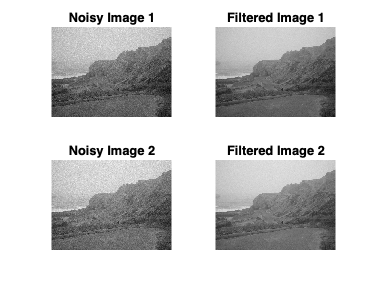

% Load the noisy images

image1 = imread('noise_1.jpg');
image2 = imread('noise_2.jpg');

% Convert images to double format for processing
image1 = im2double(image1);
image2 = im2double(image2);

% Define the size of the filter
n = 3;

% Create a Gaussian filter
sigma = sqrt(3);
[X, Y] = meshgrid(-floor(n/2):floor(n/2), -floor(n/2):floor(n/2));
gaussianFilter = exp(-(X.^2 + Y.^2) / (2 * sigma^2));
gaussianFilter = gaussianFilter / sum(gaussianFilter(:)); % Normalize the filter

% Pad the images to handle boundary cases
paddedImage1 = padarray(image1, [floor(n/2), floor(n/2)], 'replicate');
paddedImage2 = padarray(image2, [floor(n/2), floor(n/2)], 'replicate');

% Initialize the filtered images
filteredImage1 = zeros(size(image1));
filteredImage2 = zeros(size(image2));

% Slide the filter over the images and apply Gaussian filtering
for i = 1:size(image1, 1)
    for j = 1:size(image1, 2)
        % Extract the region of interest from the padded image
        region1 = paddedImage1(i:i+n-1, j:j+n-1);
        region2 = paddedImage2(i:i+n-1, j:j+n-1);
        
        % Apply Gaussian filter
        filteredImage1(i, j) = sum(region1(:) .* gaussianFilter(:));
        filteredImage2(i, j) = sum(region2(:) .* gaussianFilter(:));
    end
end

% Display the filtered images
figure;
subplot(2, 2, 1), imshow(image1), title('Noisy Image 1');
subplot(2, 2, 2), imshow(filteredImage1), title('Filtered Image 1');
subplot(2, 2, 3), imshow(image2), title('Noisy Image 2');
subplot(2, 2, 4), imshow(filteredImage2), title('Filtered Image 2');